**HODGKIN- HUXLEY MODEL**

Key reference: HODGKIN AL, HUXLEY AF. A quantitative description of membrane current

and its application to conduction and excitation in nerve. J Physiol. 1952 Aug;117(4):500-44.

doi: 10.1113/jphysiol.1952.sp004764. PMID: 12991237; PMCID: PMC1392413

The equivalent circuit of the Hodgkin-Huxley neuron consists of sodium, potassium and leak conductances together with batteries representing their respective reversal potentials in parallel with the membrane capacitor. The total membrane current at any time is thus the sum of the capacitive and ionic currents.

The basic idea of the Hodgkin-Huxley model is to use voltage and time-dependent conductances to effect a change in the membrane voltage itself. These conductances act as konbs to control the voltage because, in effect, they connect different batteries (different electromotive ion gradients) to the equivalent circuit model. Thus, a very large increase in the conductance of one ion effectively simplifies the circuit to a battery of voltage equal to its reversal potential connected to the membrane; the membrane potential therefore moves to the reversal potential for that ion.

Modelling the Hodgkin-Huxley neuron can be thought of as executing a for loop: for a given starting membrane voltage Vm= V0 at time t= t0, and a time step delta_t

1) we first calculate the voltage-dependent parameters influencing the Na and K conductances- namely the rate transitions between open and closed states (alpha and beta for the n, m and h gating variables)- these then give the steady-state open probabilities n,m,h(infinity) and time constants tau(n,m,h).

2) then we calculate the n,m,h(t) by integrating the first order differential equation for the open probabilites, and use this to calculate the Na and K conductances.

3) the Na and K currents are then computed as (conductance)(driving voltage)

4) summing the Na, K and leak currents gives the total membrane current, which, multiplied by the total effective resistance, gives the steady-state voltage the system will relax to.

5) this steady state voltage is used to calculate V(t) after time step delta_t by integrating the first order differential equation for the membrane voltage

6) this is the new voltage Vm at t= t0+delta_t, which is fed back into the loop

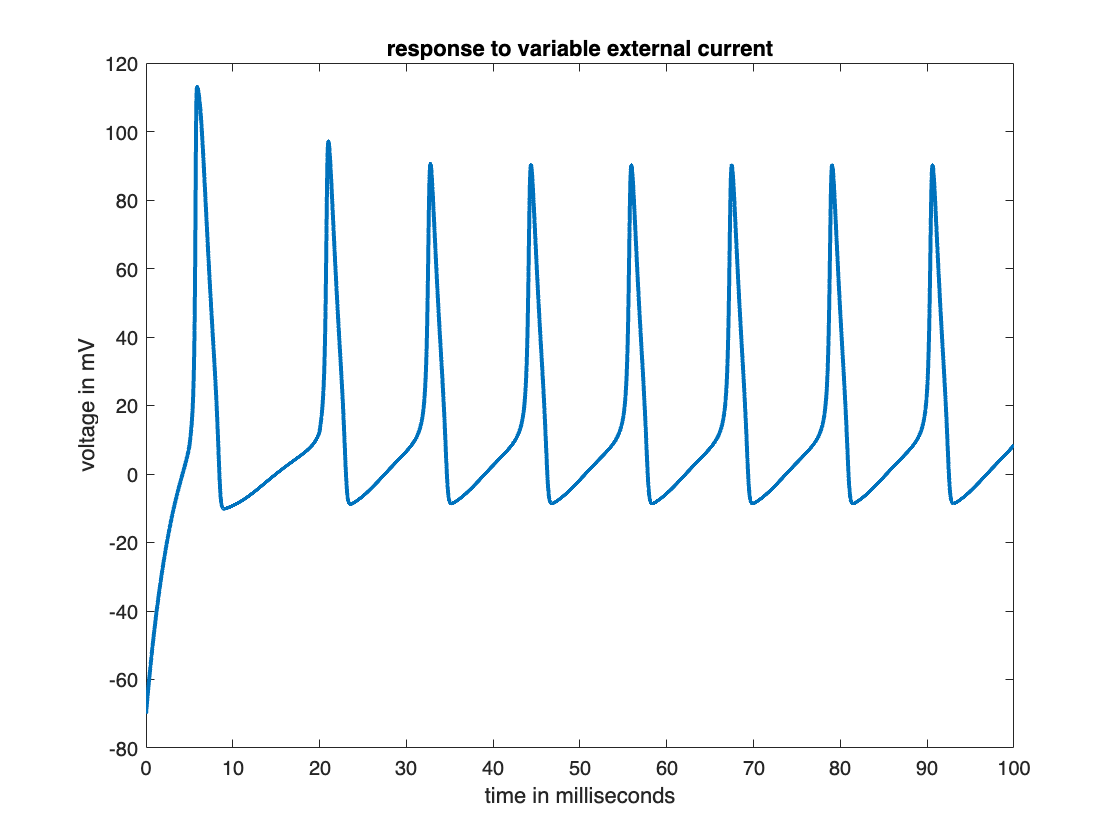

%constant parameters from the Hodgkin-Huxley paper
% conductance units in m.mho/cm^2
gbar_K= 36;
gbar_Na= 120;
g_L= 0.3;
%voltage units in mV
E_K= -12;
E_Na= 115;
E_L= 10.6;
Cap= 1; %specific membrane capacitance in units of microfarad/cm^2
A= 1; %area of the cell in cm^2
%simulation parameters
maxt= 100; % total simulation time in msec
delta_t= 0.01; %length of each time step
t= 0:delta_t:maxt;
%Set variable externally applied current across time
I(1:500) = 5; I(501:2000) = 10; I(2001:length(t)) = 20;
%initial conditions
V=-70; % resting membrane potential in mV
%initialize transition rates for m, n and h gating variables
alpha_m= zeros(size(t));
beta_m= zeros(size(t));
alpha_n= zeros(size(t));
beta_n= zeros(size(t));
alpha_h= zeros(size(t));
beta_h= zeros(size(t));
% initialize open probabilities (gating variables)
n = zeros(size(t)); %potassium activation gate
m = zeros(size(t)); %sodium activation gate
h = zeros(size(t)); %sodium inactivation gate
for i=1:length(t)-1
%calculate the transition rates
%Equations from the Hodgkin-Huxley paper
alpha_n(i) = .01 * ( (10-V(i)) / (exp((10-V(i))/10)-1) );
beta_n(i) = .125*exp(-V(i)/80);
alpha_m(i) = .1*( (25-V(i)) / (exp((25-V(i))/10)-1) );
beta_m(i) = 4*exp(-V(i)/18);
alpha_h(i) = .07*exp(-V(i)/20);
beta_h(i) = 1/(exp((30-V(i))/10)+1);
% steady-state open probabilities
n_inf= alpha_n(i)/(alpha_n(i)+ beta_n(i));
m_inf= alpha_m(i)/(alpha_m(i)+beta_m(i));
h_inf= alpha_h(i)/(alpha_h(i)+beta_h(i));
%calculate time constants
tau_n= 1/(alpha_n(i)+beta_n(i));
tau_m= 1/(alpha_m(i)+beta_m(i));
tau_h= 1/(alpha_h(i)+beta_h(i));
%update open probabilities using exponential Euler
n(i+1) = n_inf+(n(i)-n_inf)*exp(-delta_t/tau_n);
m(i+1) = m_inf+(m(i)-m_inf)*exp(-delta_t/tau_m);
h(i+1) = h_inf+(h(i)-h_inf)*exp(-delta_t/tau_h);
%calculate the conductances
g_Na= (m(i+1)^3) * gbar_Na * h(i+1);
I_Na = g_Na * (V(i)-E_Na);
g_K = (n(i+1)^4) * gbar_K;
I_K= g_K *(V(i)-E_K);
I_L = g_L *(V(i)-E_L);
% total conductance is the sum of the parallel conductances
g= g_Na +g_K+g_L;
gE= g_Na*E_Na + g_L*E_L + g_K*E_K;
V_inf = (gE+ I(i)/A) / g; % steady-state voltage
% update tau_V
tau_V = Cap/g;
% update membrane potential using exponential Euler
V(i+1) = V_inf + (V(i)-V_inf)*exp(-delta_t/tau_V);
end
%plot voltage as a function of time for
plot(t, V, 'LineWidth',2);
hold on
xlabel('time in milliseconds')
xlim();
ylabel('voltage in mV');
title('response to variable external current');

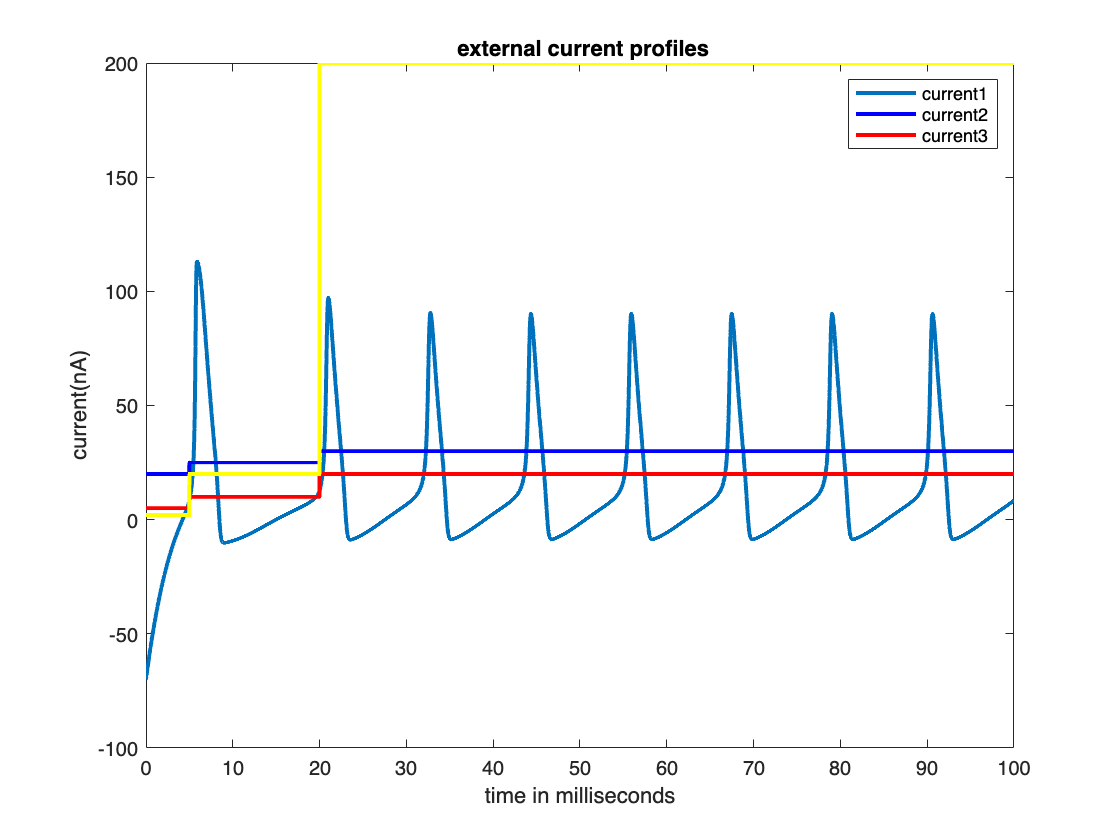

%template to model and plot different external currents
maxt= 100; % total simulation time in msec
delta_t= 0.01; %length of each time step
t= 0:delta_t:maxt;
I_3(1:500) = 2; I_3(501:2000) = 20; I_3(2001:length(t)) = 200;
I_2(1:500) = 5; I_2(501:2000) = 10; I_2(2001:length(t)) = 20;
I_1(1:500) = 20; I_1(501:2000) = 25; I_1(2001:length(t)) = 30;
plot(t, I_1, LineWidth=2, Color='b');
hold on
plot(t, I_2, LineWidth=2, Color='r');
plot(t, I_3, LineWidth=2, Color='y');
xlabel('time in milliseconds')
xlim();
ylabel('current(nA)');
title(' external current profiles');
legend('current1', 'current2', 'current3');

figure (1)
subplot(3,1, 1)
plot(V, alpha_n,  'linewidth',2);
hold on;
plot(V, beta_n, 'linewidth',2);
xlabel('V_m (mV)', 'fontsize', 10)
ylabel('transition rates (1/sec)', 'FontSize', 10);
title('n gate')
legend('alpha_n', 'beta_n')
hold off
subplot(3,1,2)
plot(V, alpha_m, 'linewidth',2)
hold on;
plot(V, beta_m, 'linewidth',2)
xlabel('V_m (mV)', 'fontsize', 10)
ylabel('transition rates (1/sec)', 'FontSize', 10);
title('m gate')
legend('alpha_m', 'beta_m')
hold off
subplot(3,1,3)
plot(V, alpha_h, 'linewidth',2);
hold on;
plot(V, beta_h, 'linewidth',2);
xlabel('V_m (mV)', 'fontsize', 10)
ylabel('transition rates (1/sec)', 'FontSize', 10);
title('h gate')
legend('alpha_h', 'beta_h')
hold off